%% 参考 https://zhuanlan.zhihu.com/p/350657915
clc;
clear;
syms s L C D R Vg;   %% D = 1-D
I = [1 0;0 1];
A = [0 -(1-D)/L;(1-D)/C -1/R/C];
B = transpose([Vg/L/(1-D) -Vg/(C*R*(1-D)^2)]);
C = [1 0];
simplify(C*inv(s*I-A)*B)%simplify为化简，inv为求逆

$$ans = -\frac{\mathrm{Vg}\,\left(C\,R\,s+2\right)}{\left(\text{D}-1\right)\,\left(R\,{\text{D}}^{2}-2\,R\,\text{D}+C\,L\,R\,s^{2}+L\,s+R\right)}$$

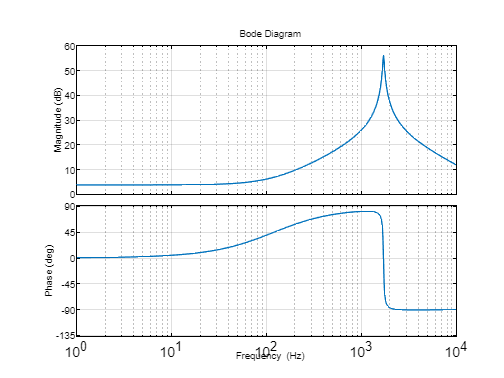


Vout = 800; %% 800V
L = 1200e-6;  %% 1mH
P = 4800;  %%4.8kW
R = Vout*Vout/P;
C = 20e-6;  %%2*470uf
Vg = 480;

D = 1-Vout/Vg;

s = tf('s');

Gid = -Vg*(C*R*s+2)/((D-1)*(R*D^2-2*R*D+C*L*R*s^2+L*s+R));

p=bodeoptions;
p.PhaseVisible='on';
p.FreqUnits='Hz';

bode(Gid,p);

grid on;

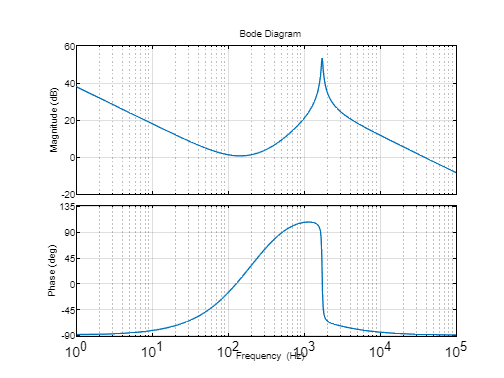


z = 2867.5;
k = 1;

Gc = (s+2000)*(s+1600)/(s*(s+10e3));
G = Gc * Gid;

bode(G,p);
grid on;

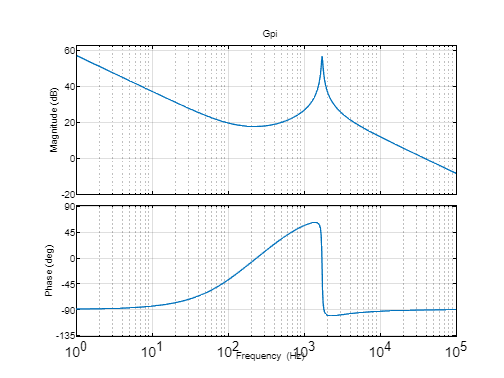


Gpi = k*(s+z)/s;

bode(Gpi*Gid,p);
grid on;
title('Gpi')

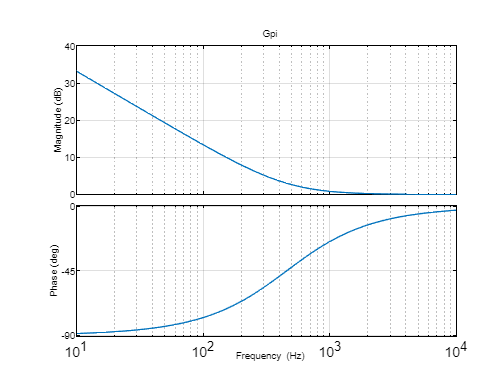


bode(Gpi,p);
grid on;
title('Gpi')


fc = 40e3;
ts = 1/fc;

dsys=c2d(Gc,ts,'tustin','z^-1') 

dsys =
 
  0.9293 z^2 - 1.777 z + 0.8493
  -----------------------------
     z^2 - 1.778 z + 0.7778
 
Sample time: 2.5e-05 seconds
Discrete-time transfer function.



tf(dsys.Numerator,dsys.Denominator,ts,'variable','z^-1')

ans =
 
  0.9293 - 1.777 z^-1 + 0.8493 z^-2
  ---------------------------------
    1 - 1.778 z^-1 + 0.7778 z^-2
 
Sample time: 2.5e-05 seconds
Discrete-time transfer function.



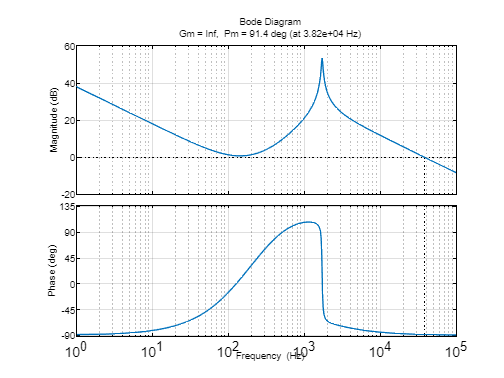

margin(G,p);
grid on;